Ncells= 607 ;Sum transient: 111926 ;nSCE: 921 ;

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 8 workers.


Elapsed time is 95.276965 seconds.
Elapsed time is 83.563042 seconds.
Elapsed time is 163.621846 seconds.
Elapsed time is 542.590630 seconds.
Elapsed time is 300.149271 seconds.
Elapsed time is 323.733109 seconds.
Elapsed time is 276.934182 seconds.
Elapsed time is 360.880055 seconds.
Elapsed time is 378.307143 seconds.
Elapsed time is 321.760931 seconds.
Elapsed time is 390.235016 seconds.
Elapsed time is 343.251423 seconds.


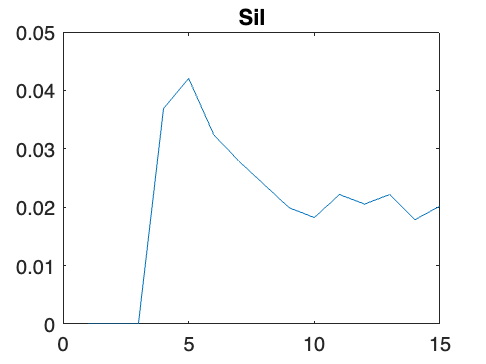

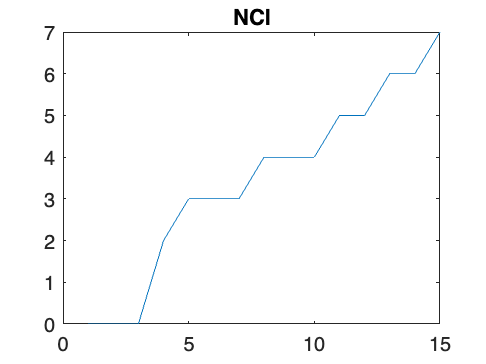

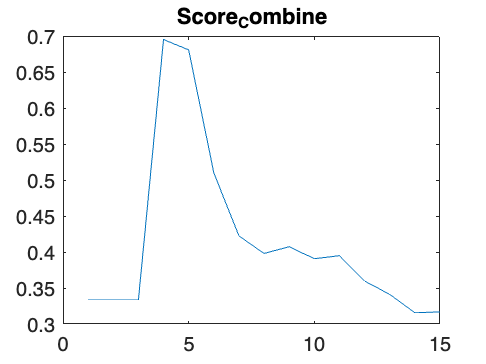

% profile on; % Activer le profiler
clear
close all
% delete(gcp('nocreate'))
% parpool ('processes',40)

if ispc
    PathSave='E:\Data\Aurelie\analysis\November2025\assembly\nocues\';%PC
    load("E:\Data\Aurelie\data\nocues\nocues.mat");%PC
    % load("E:\Data\Aurelie\data\cues\cues.mat")
elseif ismac
    PathSave='/Users/platel/Desktop/exp/brainbow_hippocampus/analysis/nocues';%mac
    load("/Users/platel/Desktop/exp/brainbow_hippocampus/analysis/final_analysis/bestnocuesold.mat")
end

% index = contains(matfile,'444152_221130');%227 

for file_num=1:numel (matfile) %54  444178 at 57  65 crash à cause gros artefact 73 plein d'assemblées ani 198, 1306
    %try
    clearvars -except file_num matfile PathSave 
    close all
    filename = '/Users/platel/Desktop/exp/brainbow_hippocampus/data/matfile/411582_230320_plane0.mat';

    %filename = '/Users/platel/Desktop/exp/brainbow_hippocampus/data/matfile/444175_221121_plane1.mat';
    % load('/Users/platel/Desktop/exp/brainbow_hippocampus/data/matfile/411582_230320_plane0.mat')
    % % % filename=string(matfile{file_num});
    % % % [path,name,ext] = fileparts(filename);
    load (filename)
    % identifier=name;
    % % session=name;
    % str = [name ' / file_num= ' num2str(file_num)];
    % fprintf('%s',str)
    % path =strcat(path ,'\');%pc
    % path=strcat(path ,'/');%mac
    %openingnwb
    preprocessing_2 %cell extraction, denoising, normalisation, baseline substraction, find SCE
    find_ncluster=true;
    %find NCl with max number of assemblies
    if find_ncluster==true
        for ncluster=4:15
            % try
            tic
                clearvars -except Sil DB CH find_ncluster SumAct MAct best_S Nz minithreshold percentile synchronous_frames MinPeakDistance MinPeakDistancesce sce_n_cells_threshold Tr1b WinRest file_num matfile PathSave nanalysis NClini nanalysis path filename F iscell speed name identifier ncluster best_NCl sampling_rate session namefull Race
                % str=['test clustering ' num2str(ncluster) ' clusters'];
                daytime = datestr(now,'yy_mm_dd_HH_MM_SS');
                % fprintf ('%s ; ',str , daytime) 
                namefull=strcat(PathSave ,daytime ,'_',name ,'/');%pc
                % mkdir (namefull) ;   % make folder for saving analysis
                NClini=ncluster;
                % NClini=5
                kmean_iter=100;
                kmeans_surrogate=50;
                kmeans_rnd_iter=10;
                savefig=0;
                clustering_assembly_2
                % fprintf('silhouette: %f',  mean(sClOK))
                best_NCl(ncluster)=NCl;
                best_S(ncluster)=mean(sCl);
                if NCl>1
                Sil(ncluster) = eva_s.CriterionValues;
                CH(ncluster) = eva_ch.CriterionValues;
                DB(ncluster) = eva_db.CriterionValues;
                else
                    Sil(ncluster) = 0;
                CH(ncluster) = 0;
                DB(ncluster) = 0;
                end


            % catch exception
            %     disp(['An error occurred in ncluster:' num2str(ncluster) ]);
            %     disp(exception.message);  % Display the error message
            % end
            toc

        end
        figure;plot(best_S);title('Sil')
        figure;plot(best_NCl);title('NCl')
        S_norm = (Sil - min(Sil)) / (max(Sil) - min(Sil));
        CH_norm = (CH - min(CH)) / (max(CH) - min(CH));
        DB_norm = (DB - min(DB)) / (max(DB) - min(DB));
        DB_inverted_norm = 1 - DB_norm;
        Score_Combine = (S_norm + CH_norm + DB_inverted_norm) / 3;
        figure;plot(Score_Combine);title('Score_Combine')
        [max_score, NClini] = max(Score_Combine);
          

    return
    end

   %     profile off; % Désactiver le profiler
   % profile viewer; % Afficher les résultats

    for nanalysis=1
        try
            
        %tic

        clearvars -except Sil CH DB find_ncluster MAct best_S Nz minithreshold percentile synchronous_frames MinPeakDistance MinPeakDistancesce sce_n_cells_threshold Tr1b WinRest file_num matfile PathSave nanalysis NClini path filename F iscell speed name identifier best_NCl sampling_rate session Race

        daytime = datestr(now,'yy_mm_dd_HH_MM_SS');
    
        namefull=strcat(PathSave ,daytime ,'_',name ,'/');%pc
        
        mkdir (namefull) ;   % make folder for saving analysis,
        
        %  disp('assembly detection')
        if find_ncluster==true
            % [a NClini]=max(best_NCl);
            [a NClini]=max(best_S);% on utilise le clustering avec la meilleure SValue initiale
            % S_norm = (Sil - min(Sil)) / (max(Sil) - min(Sil));
            % CH_norm = (CH - min(CH)) / (max(CH) - min(CH));
            % DB_norm = (DB - min(DB)) / (max(DB) - min(DB));
            % DB_inverted_norm = 1 - DB_norm;
            % Score_Combine = (S_norm + CH_norm + DB_inverted_norm) / 3;
            % [max_score, NClini] = max(Score_Combine);
            %optimal_k = optimal_k_index ;% Si la plage de k commence à 4
        else
            NClini=10;
        end
        fprintf ('clusters: %d ', NClini)
        kmean_iter=1000;
        kmeans_surrogate=100;
        kmeans_rnd_iter=10;
        savefig=1;
        clustering_assembly_2
        if NCl>1
            cell_cluster_analysis1
        else
            Q  = NaN;
            spec_normalized  = NaN;
            leak_normalized  = NaN;
            contam_normalized  = NaN;
            fracSignif_normalized  = NaN;
            Qmod_normalized  = NaN;
        end
        % fprintf('exportdata')
        exportdata
        % % % disp('saving assembly')
        save(strcat(namefull,'results.mat')) 
        
        raster_rastermap
        % plotassembly
        %  disp('brainbowassemblies')
        if NCl>1
            % fprintf('raster')
            rastercolor
        end
        if NCl>1
            % rastercolor
            brainbowassemblies2023_09_26
            % disp(' distance_calculation')
            distance_calculation
            % disp(' export_data_brainbow')
            export_data_brainbow
            % disp('saving brainbow')
            save(strcat(namefull,'brainbow.mat') )
        end


        catch exception
            disp(['An error occurred in: ' filename]);
            disp(exception.message);  % Display the error message
            disp('but analysis continue ;)')
        end

        %toc

    end
    % catch exception
    %     disp(exception.message);  % Display the error message
    % end
end